# Butterworth Filter Design

## I-  Lowpass Butterworth Transfer Function

Design a 8th-order lowpass Butterworth filter with a cutoff frequency of 21 KHz, which, for data sampled at 48 KHz, corresponds to  rad/sample. Plot its magnitude and phase responses. Use it to filter a 128-sample of sinusPulse.

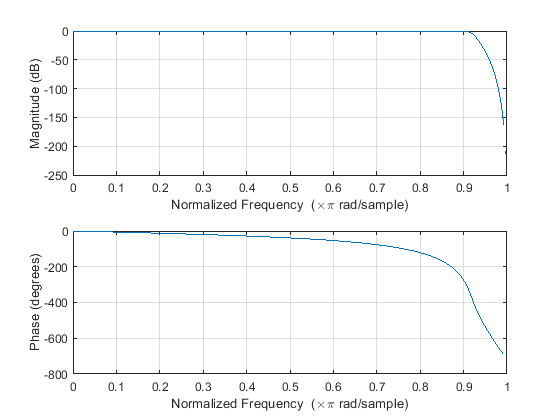

clear 
fc = 22000;         % Cutoff Frequency
fs = 48000;         % Sampling Frequency        

[b,a] = butter(8,fc/(fs/2),'low');  % Butterworth 8th-order filter
freqz(b,a)

load input_t.mat sinusPulse
dataIn = awgn(sinusPulse,12);           % SNR = 12dB : Add noise into sinusPulse
dataOut = filter(b,a,dataIn);           % Filter the dataIn using butterworth
                                        % filter parameters (a,b)           

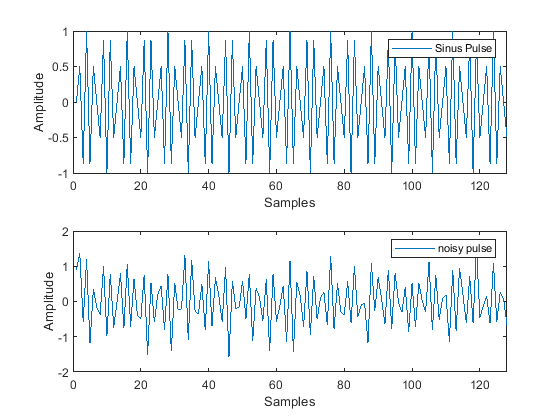

figure
%% Sinus Pulse
subplot(2,1,1)
plot(real(sinusPulse))
xlim([0 length(sinusPulse)])
legend('Sinus Pulse')
xlabel('Samples')
ylabel('Amplitude')

%% Noisy Sinus Pulse

subplot(2,1,2)
plot(real(dataIn))
legend('noisy pulse')
xlabel('Samples')
ylabel('Amplitude')
xlim([0 length(sinusPulse)])

figure
y_fft = abs(fft(dataOut));                   % Fast Fourier Transform
P2 = abs(y_fft/length(sinusPulse));          % Calculate the Modulus or just the real values
                                             % because the fft produce 
                                             % complex values
P1 = P2(1:round(length(sinusPulse)/2));      % Single Side 

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1`.

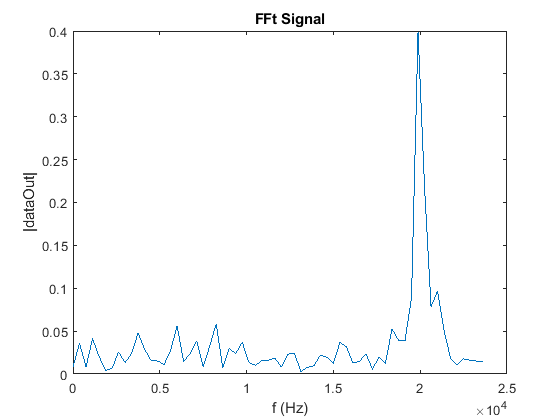

f = fs*(0:(length(sinusPulse)/2)-1)/length(sinusPulse);            % Frequency Vector
plot(f,P1)
title('FFt Signal')
xlabel('f (Hz)')
ylabel('|dataOut|')

#### References :

- [https://www.mathworks.com/help/signal/ref/butter.html](https://www.mathworks.com/help/signal/ref/butter.html)

- [https://en.wikipedia.org/wiki/Butterworth_filter](https://en.wikipedia.org/wiki/Butterworth_filter)